# ECEN 611 Homework 4: Gap Function and Mutual Inductance for Salient Pole Rotor 

`Shuxuan Chen | 132006082 | Fall 2024`

## Problem 3 

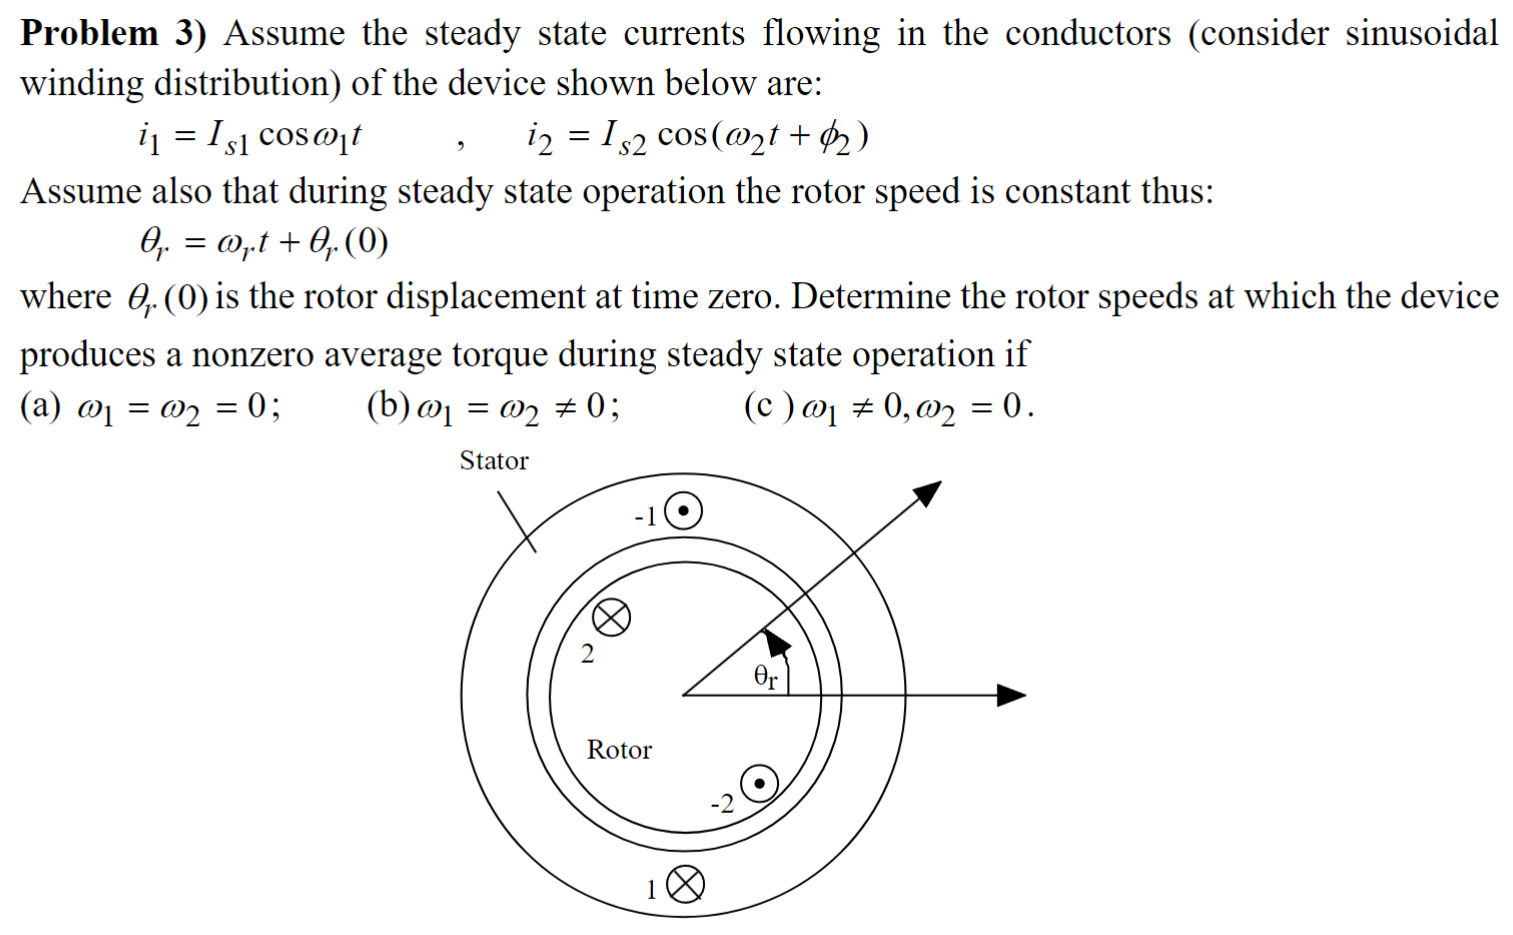

syms I positive real 
syms N_s 

syms phi 
syms theta_r 
assume( 0 <= theta_r <= 2*pi )

NS = 1;

T = 2*pi;

### Stator Counting & Winding Function 

statorCountingFunction(phi) = piecewise( ...
    0 <= phi < pi/2, 0, ...
    pi/2 <= phi < 3/2*pi, -N_s, ...
    3/2*pi <= phi < T, 0 ...
);

disp("Original Stator Counting Function φ ∈ [0 T] :")

Original Stator Counting Function φ ∈ [0 T] :


disp(statorCountingFunction(phi))

$$\left\{ \begin{array}{cl} 0 & \text{ if }\varphi \in \left[0,\frac{\pi }{2}\right)\\ -N_{s} & \text{ if }\varphi \in \left[\frac{\pi }{2},\frac{3\,\pi }{2}\right)\\ 0 & \text{ if }\varphi \in \left[\frac{3\,\pi }{2},2\,\pi \right) \end{array}\right.$$


statorCountingFunction_ext(phi) = piecewise( ...
    -2*T <= phi < -T, statorCountingFunction(phi+2*T), ...
    -T <= phi < 0, statorCountingFunction(phi+T), ...
    0 <= phi < T, statorCountingFunction(phi), ...
    T <= phi <= 2*T, statorCountingFunction(phi-T) ...
);

disp("Extended Stator Counting Function φ ∈ [-2T 2T] :")

Extended Stator Counting Function φ ∈ [-2T 2T] :


disp(statorCountingFunction_ext(phi))

$$\left\{ \begin{array}{cl} 0 & \text{ if }\varphi \in \left[-4\,\pi ,-\frac{7\,\pi }{2}\right)\\ -N_{s} & \text{ if }\varphi \in \left[-\frac{7\,\pi }{2},-\frac{5\,\pi }{2}\right)\\ 0 & \text{ if }\varphi \in \left[-\frac{5\,\pi }{2},-\frac{3\,\pi }{2}\right)\\ -N_{s} & \text{ if }\varphi \in \left[-\frac{3\,\pi }{2},-\frac{\pi }{2}\right)\\ 0 & \text{ if }\varphi \in \left[-\frac{\pi }{2},\frac{\pi }{2}\right)\\ -N_{s} & \text{ if }\varphi \in \left[\frac{\pi }{2},\frac{3\,\pi }{2}\right)\\ 0 & \text{ if }\varphi \in \left[\frac{3\,\pi }{2},\frac{5\,\pi }{2}\right)\\ -N_{s} & \text{ if }\varphi \in \left[\frac{5\,\pi }{2},\frac{7\,\pi }{2}\right)\\ 0 & \text{ if }\varphi \in \left[\frac{7\,\pi }{2},4\,\pi \right) \end{array}\right.$$


statorCountingFunction_ext_avg = 1/T * int(statorCountingFunction_ext, phi, [0 T]);
statorWindingFunction_ext(phi) = statorCountingFunction_ext - statorCountingFunction_ext_avg

$$statorWindingFunction\_ext(phi) = \left\{ \begin{array}{cl} \frac{5734161139222659\,\pi \,N_{s}}{36028797018963968} & \text{ if }\varphi \in \left[-4\,\pi ,-\frac{7\,\pi }{2}\right)\\ \frac{5734161139222659\,\pi \,N_{s}}{36028797018963968}-N_{s} & \text{ if }\varphi \in \left[-\frac{7\,\pi }{2},-\frac{5\,\pi }{2}\right)\\ \frac{5734161139222659\,\pi \,N_{s}}{36028797018963968} & \text{ if }\varphi \in \left[-\frac{5\,\pi }{2},-\frac{3\,\pi }{2}\right)\\ \frac{5734161139222659\,\pi \,N_{s}}{36028797018963968}-N_{s} & \text{ if }\varphi \in \left[-\frac{3\,\pi }{2},-\frac{\pi }{2}\right)\\ \frac{5734161139222659\,\pi \,N_{s}}{36028797018963968} & \text{ if }\varphi \in \left[-\frac{\pi }{2},\frac{\pi }{2}\right)\\ \frac{5734161139222659\,\pi \,N_{s}}{36028797018963968}-N_{s} & \text{ if }\varphi \in \left[\frac{\pi }{2},\frac{3\,\pi }{2}\right)\\ \frac{5734161139222659\,\pi \,N_{s}}{36028797018963968} & \text{ if }\varphi \in \left[\frac{3\,\pi }{2},\frac{5\,\pi }{2}\right)\\ \frac{5734161139222659\,\pi \,N_{s}}{36028797018963968}-N_{s} & \text{ if }\varphi \in \left[\frac{5\,\pi }{2},\frac{7\,\pi }{2}\right)\\ \frac{5734161139222659\,\pi \,N_{s}}{36028797018963968} & \text{ if }\varphi \in \left[\frac{7\,\pi }{2},4\,\pi \right) \end{array}\right.$$

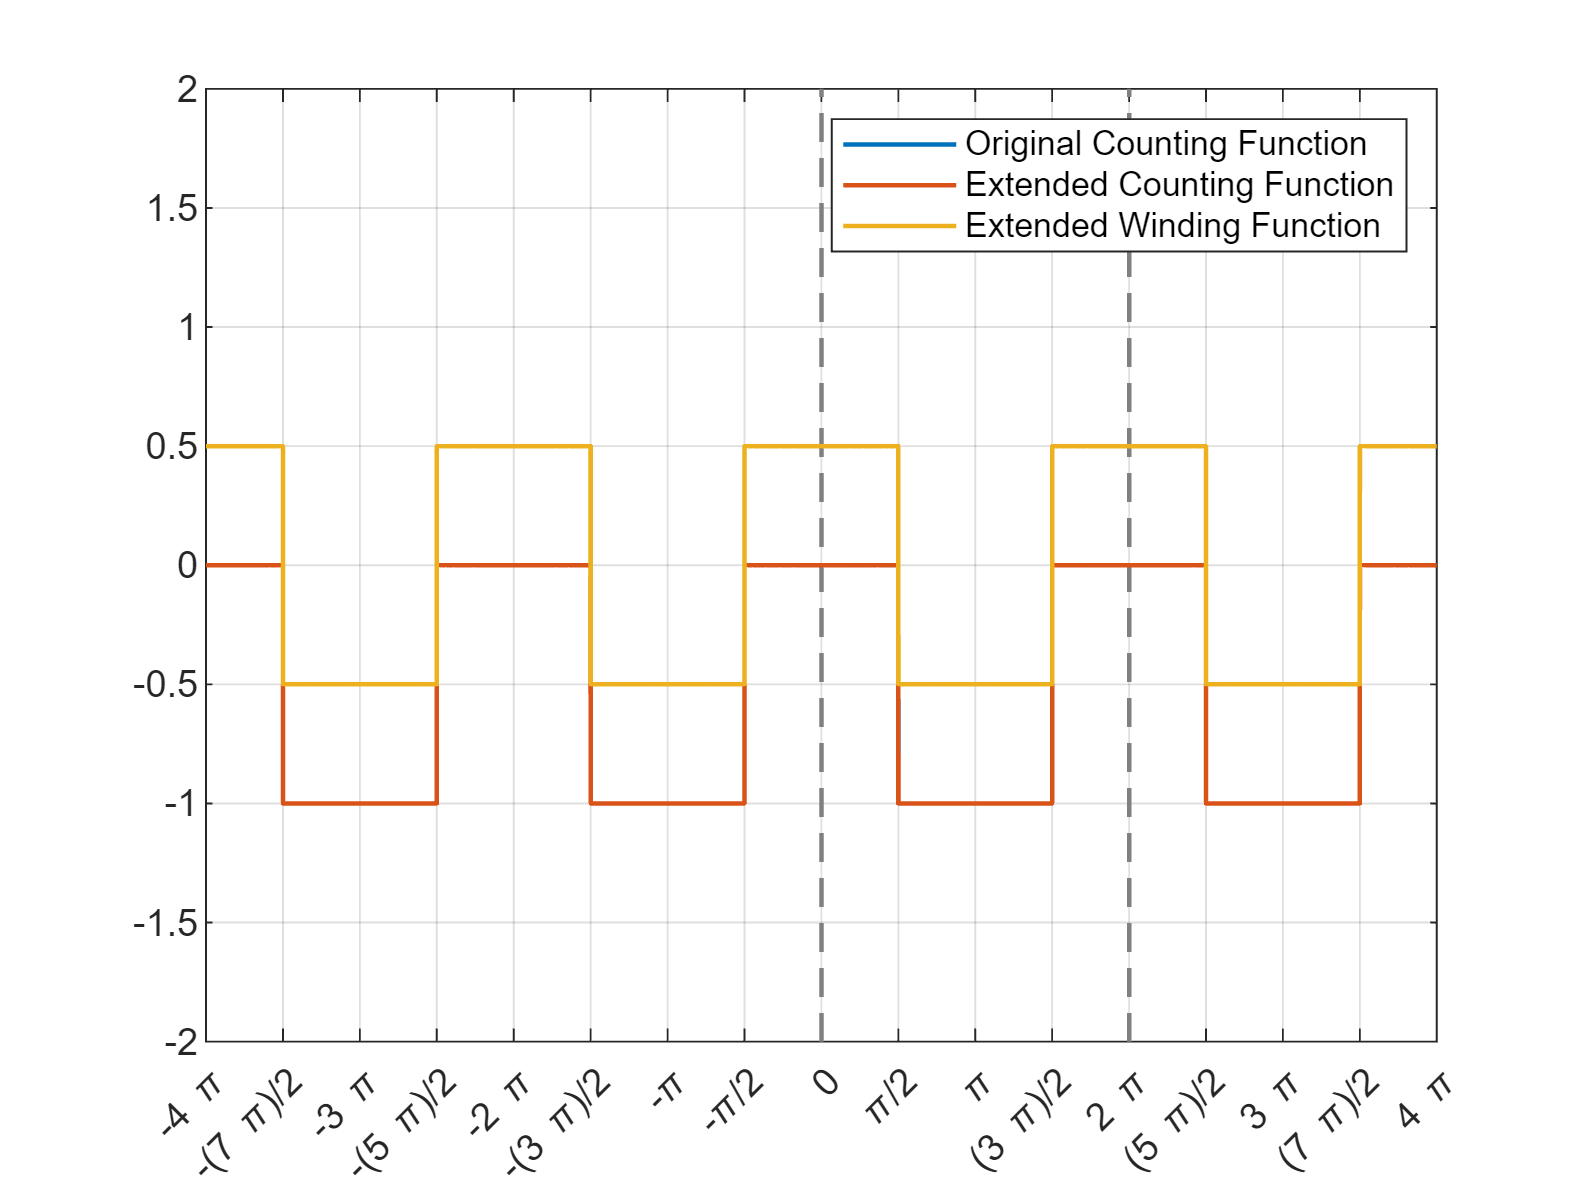


figure 
fplot(subs(statorCountingFunction(phi), N_s, NS), [-2*T 2*T], ...
    "DisplayName", "Original Counting Function", ...
    "LineWidth", 1.2)
hold on 
fplot(subs(statorCountingFunction_ext(phi), N_s, NS), [-2*T 2*T], ...
    "DisplayName", "Extended Counting Function", ...
    "LineWidth", 1.2)
fplot(subs(statorWindingFunction_ext(phi), N_s, NS), [-2*T 2*T], ...
    "DisplayName", "Extended Winding Function", ...
    "LineWidth", 1.2)
hold off 
ylim([-2 2])
grid on  
legend 

ax = gca;
S = sym(ax.XLim(1):pi/2:ax.XLim(2));
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);

### Rotor Counting & Winding Function 

syms N_r 
NR = 1;

turnsRotorNum = [0     1    -1    0 ] * N_r;   % number of turns at each location: replace Nt with 1 for simplicity  
turnsRotorPhi = [0   T/4   T/2  T/4 ];  % angle of each location

turnsRotorNumLevel = cumsum(turnsRotorNum)

$$turnsRotorNumLevel = \left(\begin{array}{cccc} 0 & N_{r} & 0 & 0 \end{array}\right)$$


rotor_winding_turning_phi = theta_r + cumsum(turnsRotorPhi)

$$rotor\_winding\_turning\_phi = \left(\begin{array}{cccc} \theta_{r} & \theta_{r}+\frac{\pi }{2} & \theta_{r}+\frac{3\,\pi }{2} & \theta_{r}+2\,\pi \end{array}\right)$$

rotorCountingFunction(phi) = turnsRotorNumLevel(1);

for k = 1:length(rotor_winding_turning_phi)-1
    
    thisPhi = rotor_winding_turning_phi(k);
    nextPhi = rotor_winding_turning_phi(k+1);

    rotorCountingFunction(phi) = piecewise(thisPhi <= phi < nextPhi, turnsRotorNumLevel(k), ...
                                           phiReference <= phi < thisPhi, rotorCountingFunction);
end 

#### Original Rotor Counting Function φ ∈ [θr θr+T]

disp("Original Rotor Counting Function: ");

Original Rotor Counting Function: 


disp(rotorCountingFunction(phi));

$$\left\{ \begin{array}{cl} 0 & \text{ if }\varphi <\theta_{r}+2\,\pi \wedge \theta_{r}+\frac{3\,\pi }{2}\leq \varphi \\ N_{r} & \text{ if }\varphi <\theta_{r}+\frac{3\,\pi }{2}\wedge \theta_{r}+\frac{\pi }{2}\leq \varphi \wedge 0\leq \varphi \\ 0 & \text{ if }\varphi <\theta_{r}+\frac{\pi }{2}\wedge 0\leq \varphi \wedge \left(\varphi <\theta_{r}\vee \left(\theta_{r}\leq \varphi \wedge 2\,\varphi <2\,\theta_{r}+\pi \right)\right) \end{array}\right.$$

#### Extended Rotor Counting Function φ ∈ [θr-2T θr+2T]

rotorCountingFunction_ext(phi) = piecewise( ...
    theta_r - 2*T <= phi < theta_r - T, rotorCountingFunction(phi+2*T), ...
    theta_r - T <= phi < theta_r,       rotorCountingFunction(phi+T), ...
    theta_r <= phi < theta_r + T,       rotorCountingFunction(phi), ...
    theta_r + T <= phi < theta_r + 2*T, rotorCountingFunction(phi-T) ...
)

#### Extended Rotor Winding Function φ ∈ [θr-2T θr+2T]

% assume( theta < T )

rotorCountingFunction_ext_avg = 1/T * int( subs(rotorCountingFunction_ext, theta_r, THETA_R), phi, [0 T]);
rotorWindingFunction_ext = rotorCountingFunction_ext - rotorCountingFunction_ext_avg

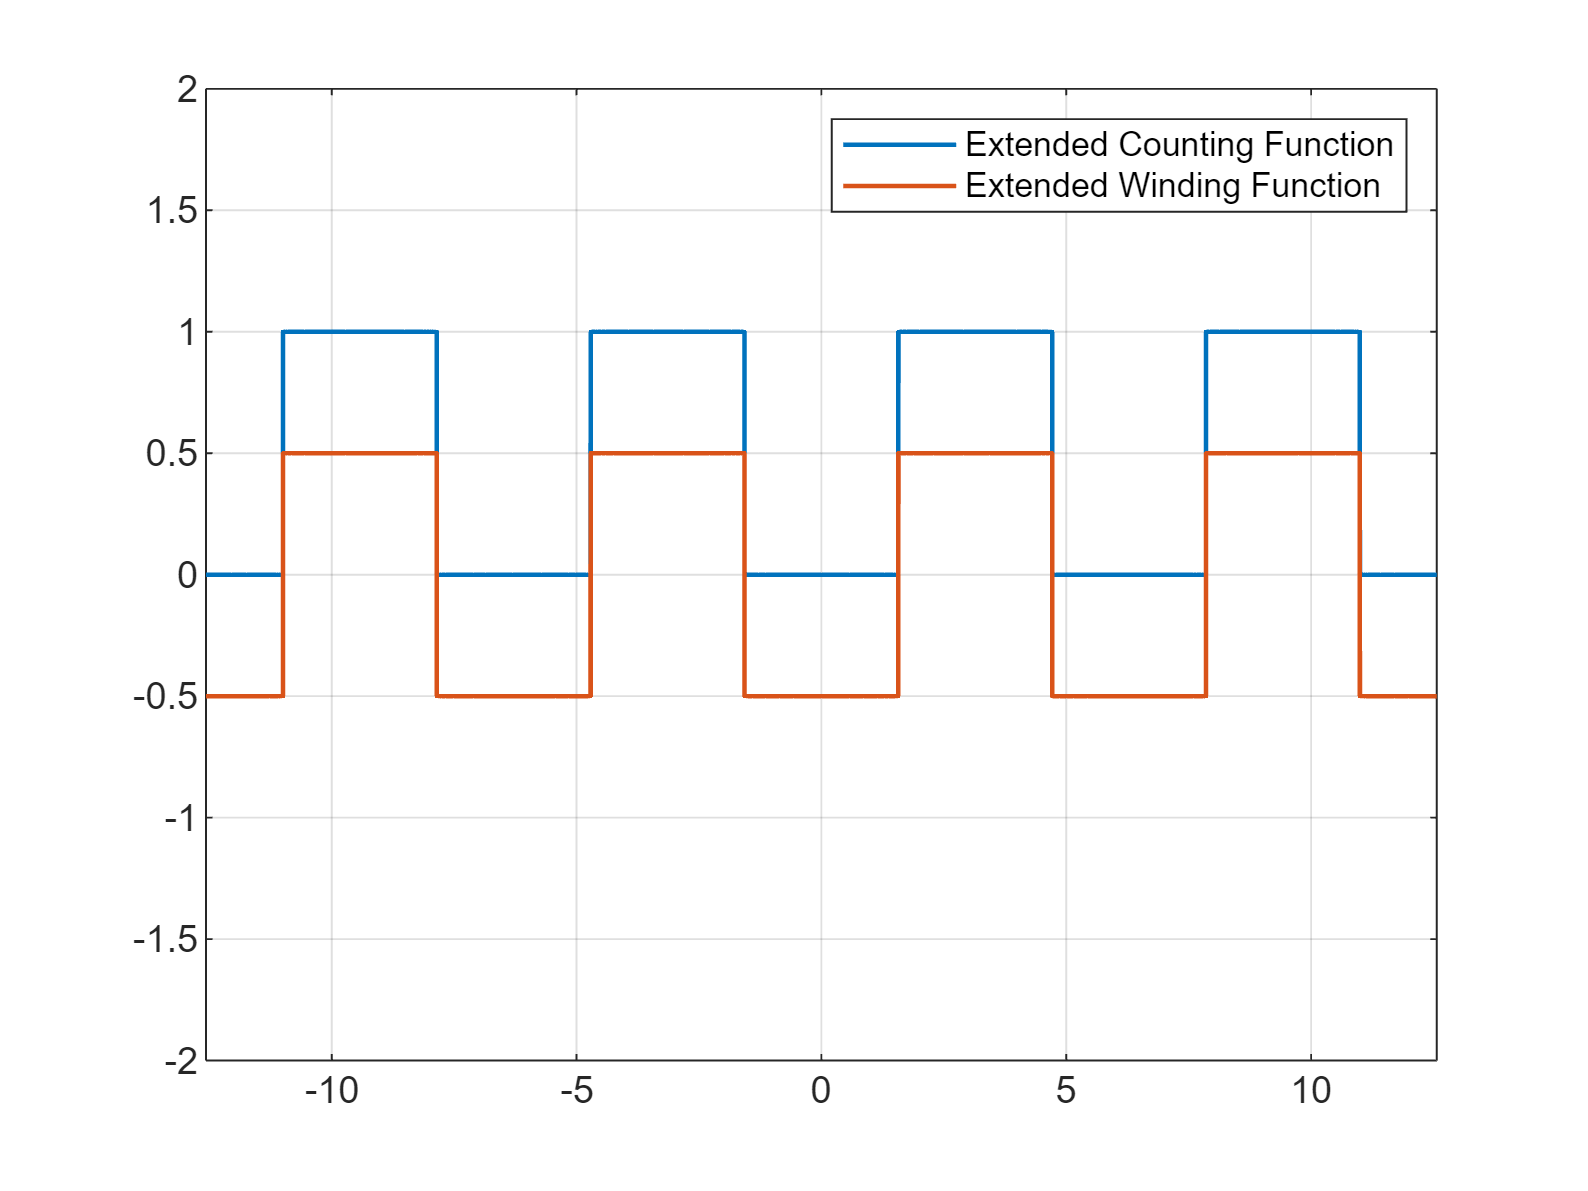


figure 
fplot(subs(rotorCountingFunction_ext(phi),[theta_r N_r], [0 NR]), [-2*T 2*T], ...
    "DisplayName", "Extended Counting Function", ...
    "LineWidth", 1.2)
hold on 
fplot(subs(rotorWindingFunction_ext(phi),[theta_r N_r], [0 NR]), [-2*T 2*T], ...
    "DisplayName", "Extended Winding Function", ...
    "LineWidth", 1.2)
hold off 
ylim([-2 2])
grid on  
legend 

### Stator Winding Magnetizing Inductance

syms mu_o r l g 
Lss = mu_o*r*l/g * int( statorWindingFunction_ext * statorWindingFunction_ext, ...
                     phi, [0 T]);

Lss_simplified = subs( simplify( vpa(Lss) ) )

$$Lss\_simplified = \frac{1.571\,{N_{s}}^{2}\,l\,\mu_{o}\,r}{g}$$

Lss_simplified = subs( simplify( vpa(Lss) ), N_s^2*l*mu_o*r/g, 1 )

$$Lss\_simplified = 1.571$$

### Rotor Winding Magnetizing Inductance

syms mu_o r l g 
Lrr = mu_o*r*l/g * int( rotorWindingFunction_ext * rotorWindingFunction_ext, ...
                        phi, [0 T]);

Lrr_simplified = subs( simplify( vpa(Lrr) ) )

$$Lrr\_simplified = \left\{ \begin{array}{cl} \frac{1.571\,{N_{r}}^{2}\,l\,\mu_{o}\,r}{g} & \text{ if }\theta_{r}=4.712\vee \theta_{r}=1.571\vee \theta_{r}=0\\ \frac{1.571\,{N_{r}}^{2}\,l\,\mu_{o}\,r}{g} & \text{ if }4.712<\theta_{r}\vee \left(\theta_{r}<1.571\wedge \theta_{r}\neq 0\right)\vee \theta_{r}\in \left(1.571,4.712\right) \end{array}\right.$$

### Stator-Rotor Winding Mutual Inductance 

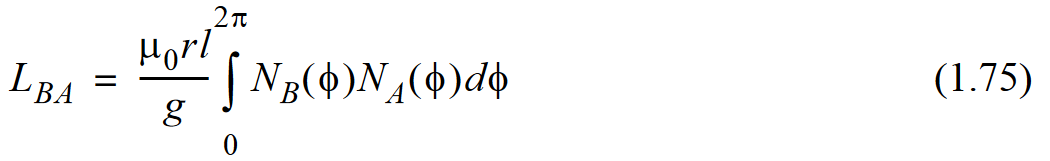

Lsr_integrand = rotorWindingFunction_ext * statorWindingFunction_ext;
Lsr = mu_o*r*l/g * int(Lsr_integrand, phi, [0 T]); 

digits(4)
Lsr_simplified = subs( simplify( vpa(Lsr) ), N_r*N_s*l*mu_o*r/g, 1 )
figure 

fplot(Lsr_simplified, [0 T], ...
    "LineWidth", 1.2)
ylim([-3 3])
grid on  
title("Stator-Rotor Winding Mutual Inductance")

ax = gca;
S = sym(ax.XLim(1):pi/4:ax.XLim(2));
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);

### Torque Production

syms I_s1 omega_1 I_s2 omega_2 
syms t 
syms phi_2 omega_r theta_r 

magnitude = [I_s1 I_s2];
angle = [ omega_1*t omega_2*t + phi_2 ];
current = magnitude .* cos(angle);
i1 = current(1)

$$i1 = I_{\mathrm{s1}}\,\cos\left(\omega_{1}\,t\right)$$

i2 = current(2)

$$i2 = I_{\mathrm{s2}}\,\cos\left(\varphi_{2}+\omega_{2}\,t\right)$$

#### Reluctance Torque 

reluctanceTorque = 1/2 * (i1^2*diff(Lss,theta_r) + i2^2*diff(Lrr,theta_r))

$$reluctanceTorque = \left\{ \begin{array}{cl} 0 & \text{ if }\theta_{r}\in \left(\frac{3\,\pi }{2},2\,\pi \right)\vee \theta_{r}\in \left(\frac{\pi }{2},\frac{3\,\pi }{2}\right)\vee \left(\theta_{r}<\frac{\pi }{2}\wedge \theta_{r}\neq 0\right) \end{array}\right.$$

#### Alignment Torque 

alignmentTorque = i1 * i2 * diff(Lsr,theta_r);
alignmentTorque_simplified = simplify( vpa(alignmentTorque) )

$$alignmentTorque\_simplified = \left\{ \begin{array}{cl} \frac{I_{\mathrm{s1}}\,I_{\mathrm{s2}}\,N_{r}\,N_{s}\,l\,\mu_{o}\,r\,\cos\left(\varphi_{2}+\omega_{2}\,t\right)\,\cos\left(\omega_{1}\,t\right)}{g} & \text{ if }\left(\theta_{r}<1.571\wedge \theta_{r}\neq 0\right)\vee \theta_{r}\in \left(1.571,3.142\right)\\ -\frac{1.0\,I_{\mathrm{s1}}\,I_{\mathrm{s2}}\,N_{r}\,N_{s}\,l\,\mu_{o}\,r\,\cos\left(\varphi_{2}+\omega_{2}\,t\right)\,\cos\left(\omega_{1}\,t\right)}{g} & \text{ if }\theta_{r}\in \left(3.142,4.712\right)\vee \theta_{r}\in \left(4.712,6.283\right) \end{array}\right.$$

#### Total Torque

totalTorque = reluctanceTorque + alignmentTorque_simplified

$$totalTorque = \left\{ \begin{array}{cl} \frac{I_{\mathrm{s1}}\,I_{\mathrm{s2}}\,N_{r}\,N_{s}\,l\,\mu_{o}\,r\,\cos\left(\varphi_{2}+\omega_{2}\,t\right)\,\cos\left(\omega_{1}\,t\right)}{g} & \text{ if }\theta_{r}\in \left(0,\frac{\pi }{2}\right)\vee \theta_{r}\in \left(1.571,3.142\right)\vee \theta_{r}<0\\ -\frac{1.0\,I_{\mathrm{s1}}\,I_{\mathrm{s2}}\,N_{r}\,N_{s}\,l\,\mu_{o}\,r\,\cos\left(\varphi_{2}+\omega_{2}\,t\right)\,\cos\left(\omega_{1}\,t\right)}{g} & \text{ if }\theta_{r}\in \left(4.712,2\,\pi \right)\vee \theta_{r}\in \left(3.142,\frac{3\,\pi }{2}\right) \end{array}\right.$$

### Rotor Speed 

Determine the rotor speeds at which the device produces a nonzero average torque during steady state operation if

(a) When ω1 = ω2 = 0 (DC Current Supply)